Analysis of the homogenous competition setup over a range of alphas

Uses the data file **competition/alphadat.m**

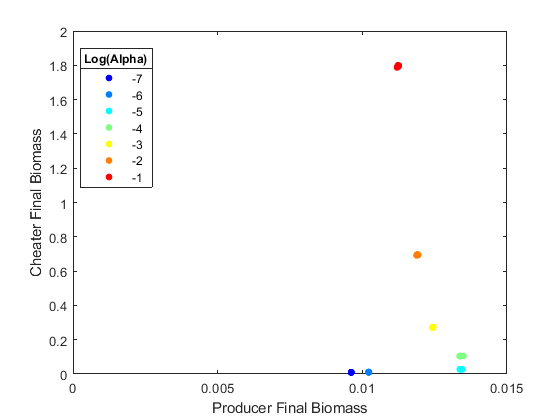

%Analysis of just the "one for all" maintenance method
alphadat = sortrows(alphadat,'alpha');
d = alphadat(~alphadat.maint_replaced,:);
d = d(d.ts == .1,:);

%scatter plot of all data
[nrows, ncols] = size(d);
ualpha = unique(d.alpha);
colors = jet(length(ualpha));
legendstr = arrayfun(@(x) num2str(x),log(ualpha),'uniformoutput',false);
%hold on;
%figure();
for i = 1:nrows
    p(i) = d.biomass_producer{i}(end);
    c(i) = d.biomass_cheater{i}(end);
    groups(i) = find(ualpha == d.alpha(i));
end
g = gscatter(p,c,groups,colors);
leg = legend(g,legendstr);
title(leg,'Log(Alpha)');
xlim([0 0.015]);
ylim([0 2]);
xlabel('Producer Final Biomass');
ylabel('Cheater Final Biomass');

%refline(1,0);
%hold off;

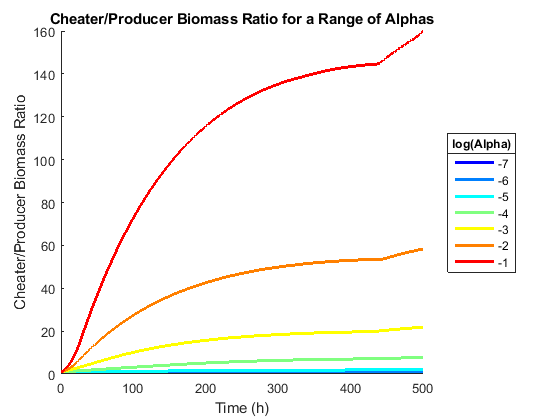



%get the means
t = cell(length(ualpha),1);
producers = cell(length(ualpha),1);
cheaters = cell(length(ualpha),1);
ratio = cell(length(ualpha),1);
prodmean = cell(length(ualpha),1);
cheatmean = cell(length(ualpha),1);
producersd = cell(length(ualpha),1);
cheatersd = cell(length(ualpha),1);
ratiosd = cell(length(ualpha),1);
total = cell(length(ualpha),1);
glc = cell(length(ualpha),1);
glcmean = cell(length(ualpha),1);
glcsd = cell(length(ualpha),1);
cel = cell(length(ualpha),1);
celmean = cell(length(ualpha),1);
celsd = cell(length(ualpha),1);
for i = 1:length(ualpha)
    a = ualpha(i);
    subtab = d(d.alpha == a,:);
    producers{i} = horzcat(subtab.biomass_producer{:});
    prodmean{i} = mean(producers{i},2);
    prodsd{i} = std(producers{i}');
    cheaters{i} = horzcat(subtab.biomass_cheater{:});
    cheatmean{i} = mean(cheaters{i},2);
    cheatsd{i} = std(cheaters{i}');
    ratio{i} = cheatmean{i} ./ prodmean{i};
    ratiosd{i} = std(cheaters{i}' ./ producers{i}');
    t{i} = subtab.t{1};
    
    glc{i} = horzcat(subtab.glc_amt{:});
    glcmean{i} = mean(glc{i},2);
    glcsd{i} = std(glc{i}');
    cel{i} = horzcat(subtab.cellulose_amt{:});
    celmean{i} = mean(cel{i},2);
    celsd{i} = std(cel{i}');
end

[nrows,ncols] = size(ratio);
legendstr = arrayfun(@(x) num2str(x),log(ualpha),'uniformoutput',false);
colors = jet(nrows);
figure();
hold on;
for i = 1:nrows
    plot(t{i},ratio{i},'color',colors(i,:),'linewidth',2);
%     xedge = [t{i}; flip(t{i})];
%     y_down = ratio{i} - (1.96 * ratiosd{i});
%     y_up = ratio{i} + (1.96 * ratiosd{i});
%     yedge = [y_down; flip(y_up)];
%     fill(xedge,yedge,colors(i,:),'FaceAlpha',0.2,'EdgeColor','none','HandleVisibility','off');
end
leg = legend(legendstr,'location','eastoutside');
title(leg,'log(Alpha)');
title('Cheater/Producer Biomass Ratio for a Range of Alphas');
xlabel('Time (h)');
ylabel('Cheater/Producer Biomass Ratio');
hold off;

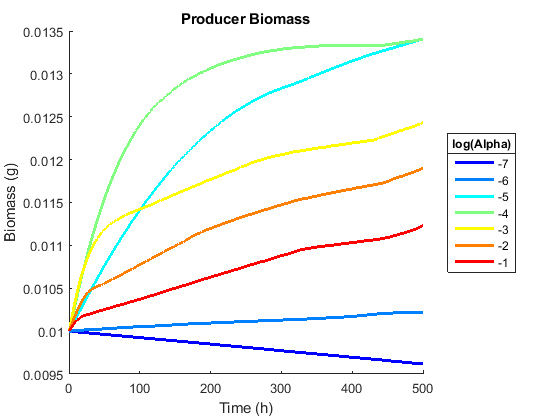


nrows = length(ualpha);
colors = jet(nrows);
figure();
hold on;

for i = 1:nrows
    plot(t{i},prodmean{i},'color',colors(i,:),'linewidth',2);
end
title('Producer Biomass');
xlabel('Time (h)');
ylabel('Biomass (g)');
leg = legend(legendstr,'location','eastoutside');
title(leg,'log(Alpha)');
hold off;

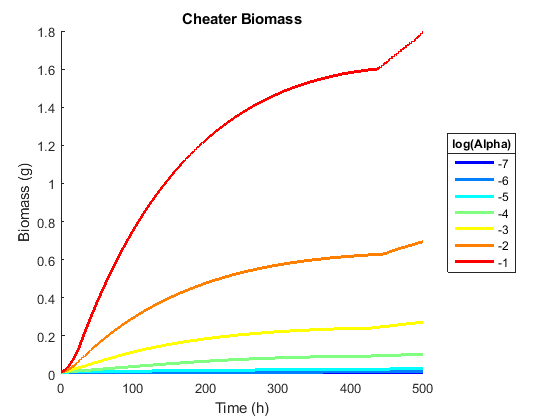


figure();
hold on;
for i = 1:nrows
    plot(t{i},cheatmean{i},'color',colors(i,:),'linewidth',2);
end
title('Cheater Biomass');
xlabel('Time (h)');
ylabel('Biomass (g)');
leg = legend(legendstr,'location','eastoutside');
title(leg,'log(Alpha)');
hold off;

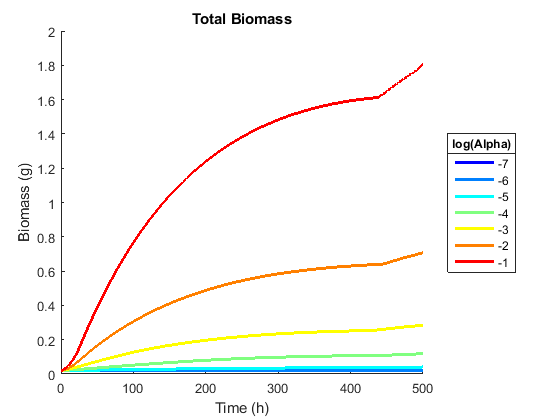


figure();
hold on;
for i = 1:nrows
    plot(t{i},cheatmean{i} + prodmean{i},'color',colors(i,:),'linewidth',2);
end
title('Total Biomass');
xlabel('Time (h)');
ylabel('Biomass (g)');
leg = legend(legendstr,'location','eastoutside');
title(leg,'log(Alpha)');
hold off;

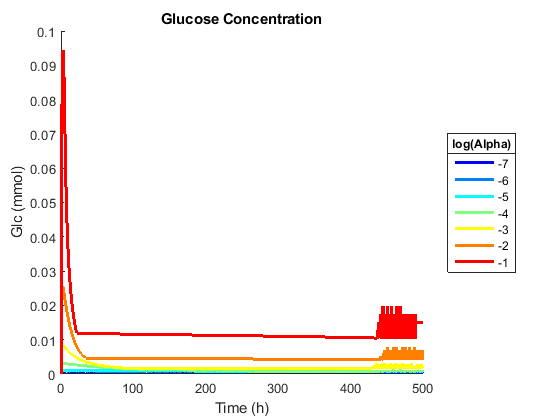


figure();
hold on;
for i = 1:nrows
    plot(t{i},glcmean{i},'color',colors(i,:),'linewidth',2);
end
title('Glucose Concentration');
xlabel('Time (h)');
ylabel('Glc (mmol)');
leg = legend(legendstr,'location','eastoutside');
title(leg,'log(Alpha)');
hold off;

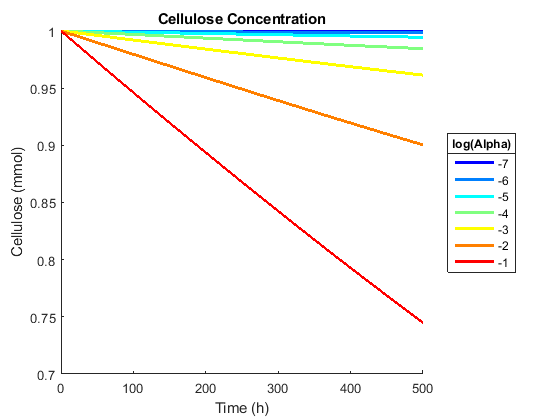


figure();
hold on;
for i = 1:nrows
    plot(t{i},celmean{i},'color',colors(i,:),'linewidth',2);
end
title('Cellulose Concentration');
xlabel('Time (h)');
ylabel('Cellulose (mmol)');
leg = legend(legendstr,'location','eastoutside');
title(leg,'log(Alpha)');
hold off;